Rainey Aberle

28 September 2020

#### *Script to calculate the ice flux into the Crane centerline from tributaries for 2011 speeds and geometries.*

- *Load Crane centerline, width, tributary geometries, and velocities at the flux gates & plot regional map. *

- *Calculate the total volume flux input from each tributary to the Crane centerline. *

- *Integrate over the width and distance between centerline points to calculate thickness input at each point. *

- *Adjust for a parabolic input, so that the largest ice flux rate enters in the center of each tributary. *

**1. Load Crane centerline, width, geometry, and velocity observations for the tributaries.**

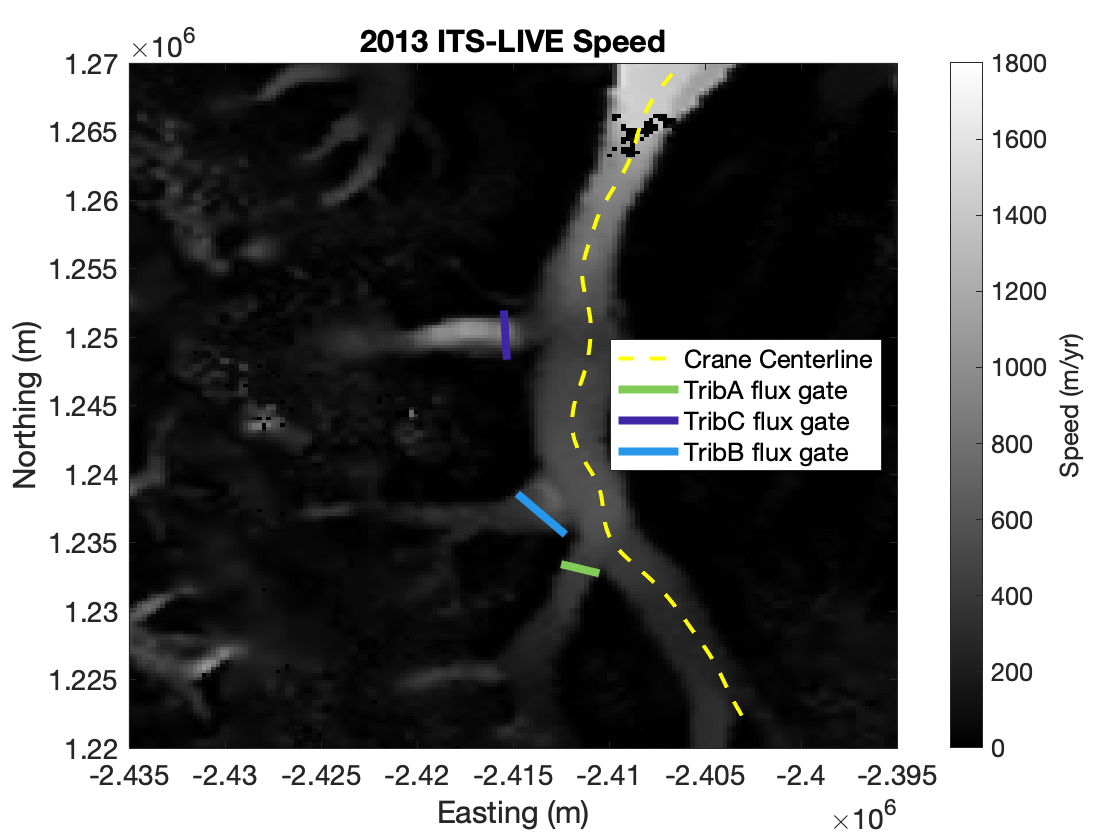

clear; close all;

% Define home path
homepath = '/Users/raineyaberle/Desktop/Research/CraneModeling/CraneGlacier_flowlinemodeling/';
cd([homepath,'inputs-outputs/']);

% Add path to velocity data
addpath([homepath,'data/velocities/']);

% Load Crane centerline coordinates and width along centerline
    cl.x = load('Crane_centerline.mat').x; cl.y = load('Crane_centerline.mat').y;
    cl.W = load('calculatedWidth.mat').width.W;
    % Define x as distance along the centerline
    x0 = zeros(1,length(cl.x));
    for i=2:length(cl.x)
        x0(i)=sqrt((cl.x(i)-cl.x(i-1))^2+(cl.y(i)-cl.y(i-1))^2)+x0(i-1);
    end

    load('TributaryA.mat');
        tribA.x_fg=xa_w; tribA.y_fg=ya_w; 
        tribA.h_cl = ha_cl; tribA.hb_cl = hba_cl; 
        tribA.x_cl = xa_cl; tribA.y_cl = ya_cl;
        clear xa* ya* ha* hb*
    tribB.x_fg = load('TributaryB.mat').x; tribB.y_fg = load('TributaryB.mat').y;
    tribC.x_fg = load('TributaryC.mat').x; tribC.y_fg = load('TributaryC.mat').y;
    
% Load 2011 TSX velocities along tributary flux gates
%     load('LarsenB_TSX_velocities.mat');
%     u.x = {V(15).x}; u.x = u.x{:,:}; u.y = {V(15).y}; u.y = u.y{:,:};
%     u.U = {V(15).speed}; u.U = u.U{:,:}; % m/day
%     u.U = u.U.*365; % m/yr
%     u.err = {V(15).speed_err}; u.err = u.err{:,:}; % m/day
%     u.err = u.err.*365; % m/yr
u.x = ncread('ANT_G0240_2013.nc','x')'; u.y = ncread('ANT_G0240_2013.nc','y')';
u.U = ncread('ANT_G0240_2013.nc','v')'; % m/yr
u.err = ncread('ANT_G0240_2013.nc','v_err')'; % m/yr
    
    tribA.U_fg = interp2(u.x,u.y,u.U,tribA.x_fg,tribA.y_fg); % m/yr TribA flux gate
    tribB.U_fg = interp2(u.x,u.y,u.U,tribB.x_fg,tribB.y_fg); % m/yr TribB flux gate 
    tribC.U_fg = interp2(u.x,u.y,u.U,tribC.x_fg,tribB.y_fg); % m/yr TribC flux gate
        
% Regrid all variables for centerline and flux gates with dx spacing
 dx = 300; % grid spacing (m)
 
    % Centerline
        x_i = x0; % rename initialization distance vector
        L = x0(end); % length of centerline (m)
        x = 0:dx:L; % desired distance vector (m from ice divide)
        cl.x = interp1(x_i,cl.x,x,'linear','extrap');
        cl.y = interp1(x_i,cl.y,x,'linear','extrap');
    % TribA
        xa_i = zeros(1,length(tribA.x_fg));
        for i=2:length(tribA.x_fg)
            xa_i(i)=sqrt((tribA.x_fg(i)-tribA.x_fg(i-1))^2+(tribA.y_fg(i)-tribA.y_fg(i-1))^2)+xa_i(i-1);
        end
        tribA.x = 0:dx:xa_i(end);
        tribA.U_fg = interp1(xa_i,tribA.U_fg,tribA.x);
        tribA.x_fg = interp1(xa_i,tribA.x_fg,tribA.x); tribA.y_fg = interp1(xa_i,tribA.y_fg,tribA.x); 
    % TribB
        xb_i = zeros(1,length(tribB.x_fg));
        for i=2:length(tribB.x_fg)
            xb_i(i)=sqrt((tribB.x_fg(i)-tribB.x_fg(i-1))^2+(tribB.y_fg(i)-tribB.y_fg(i-1))^2)+xb_i(i-1);
        end
        tribB.x = 0:dx:xb_i(end);
        tribB.U_fg = interp1(xb_i,tribB.U_fg,tribB.x);
        tribB.x_fg = interp1(xb_i,tribB.x_fg,tribB.x); tribB.y_fg = interp1(xb_i,tribB.y_fg,tribB.x);
    % TribC
        xc_i = zeros(1,length(tribC.x_fg));
        for i=2:length(tribC.x_fg)
            xc_i(i)=sqrt((tribC.x_fg(i)-tribC.x_fg(i-1))^2+(tribC.y_fg(i)-tribC.y_fg(i-1))^2)+xc_i(i-1);
        end
        tribC.x = 0:dx:xc_i(end);
        tribC.U_fg = interp1(xc_i,tribC.U_fg,tribC.x);
        tribC.x_fg = interp1(xc_i,tribC.x_fg,tribC.x); tribC.y_fg = interp1(xc_i,tribC.y_fg,tribC.x);
        
    clearvars *_i
    
    col = parula(4); % color scheme for plotting tributaries
    
% Interpolate surface and velocity error
    tribA.U_err_fg = interp2(u.x,u.y,u.err,tribA.x_fg,tribA.y_fg); tribA.h_err = 25.*ones(1,length(tribA.x));
    tribB.U_err_fg = interp2(u.x,u.y,u.err,tribB.x_fg,tribB.y_fg); tribB.h_err = 25.*ones(1,length(tribB.x));
    tribC.U_err_fg = interp2(u.x,u.y,u.err,tribC.x_fg,tribC.y_fg); tribC.h_err = 25.*ones(1,length(tribC.x));

% Plot velocity map
figure; 
    I=imagesc(u.x,u.y,u.U,[0 1800]); colormap gray
    xlabel('Easting (m)'); ylabel('Northing (m)');
    c=colorbar; c.Label.String = ('Speed (m/yr)');
    title('2013 ITS-LIVE Speed'); legend('Location','east');
    set(gca,'fontsize',14,'YDir','normal');
    hold on; plot(cl.x,cl.y,'--y','linewidth',2,'displayname','Crane Centerline'); 
    plot(tribC.x_fg,tribC.y_fg,'-','color',col(3,:),'LineWidth',4,'DisplayName','TribA flux gate');
    plot(tribA.x_fg,tribA.y_fg,'-','color',col(1,:),'LineWidth',4,'DisplayName','TribC flux gate');
    plot(tribB.x_fg,tribB.y_fg,'-','color',col(2,:),'LineWidth',4,'DisplayName','TribB flux gate'); 
    xlim([-2.435e6 -2.395e6]); ylim([1.22e6 1.27e6]); 

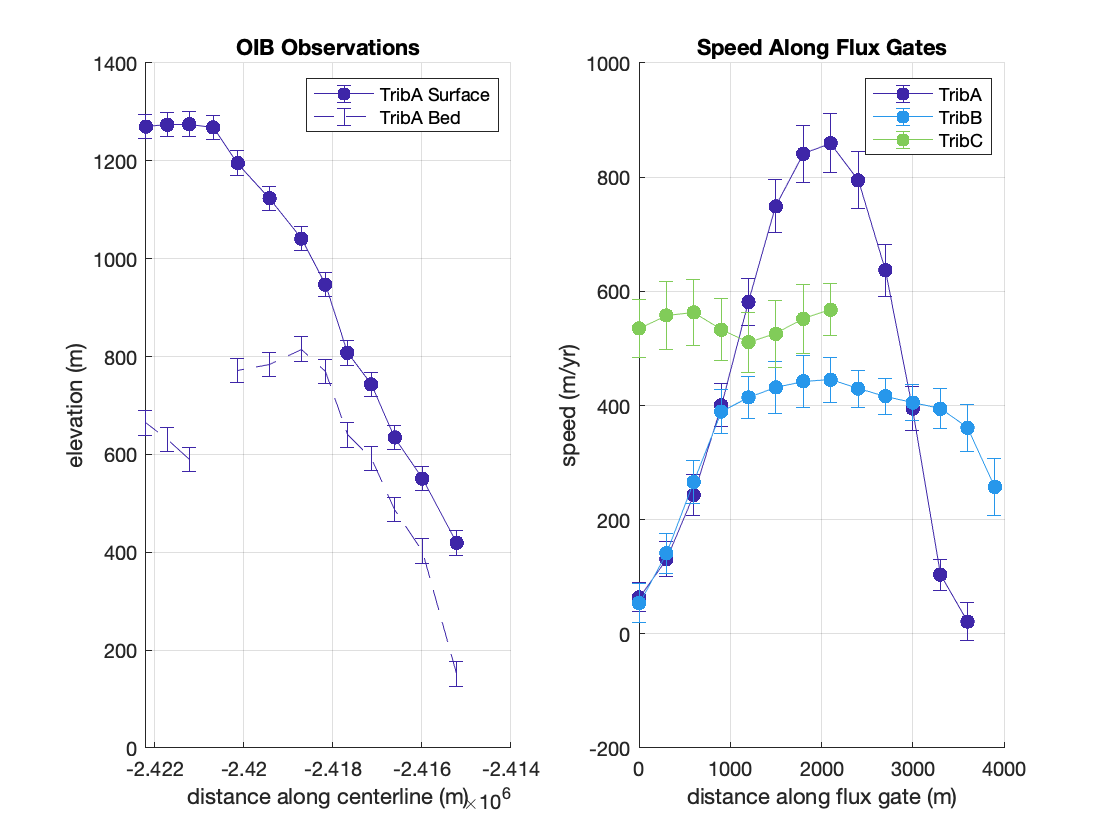

% Plot velocity, surface, and bed observations for tributaries
    figure; 
        subplot(1,2,1); hold on; % ice surface
        errorbar(tribA.x_cl,tribA.h_cl,tribA.h_err,'.-','color',col(1,:),'markersize',20,'displayname','TribA Surface');
        errorbar(tribA.x_cl,tribA.hb_cl,tribA.h_err,'--','color',col(1,:),'DisplayName','TribA Bed');
        xlabel('distance along centerline (m)'); ylabel('elevation (m)'); title('OIB Observations');
        grid on; legend;
        
        subplot(1,2,2); hold on; % ice speed
        errorbar(tribA.x,tribA.U_fg,tribA.U_err_fg,'.-','color',col(1,:),'markersize',20,'displayname','TribA');
        errorbar(tribB.x,tribB.U_fg,tribB.U_err_fg,'.-','color',col(2,:),'markersize',20,'displayname','TribB');
        errorbar(tribC.x,tribC.U_fg,tribC.U_err_fg,'.-','color',col(3,:),'markersize',20,'displayname','TribC');
        xlabel('distance along flux gate (m)'); ylabel('speed (m/yr)'); title('Speed Along Flux Gates');
        grid on; legend;

**    Plot regional map with Crane Glacier centerline, Tributary A centerline & width.**

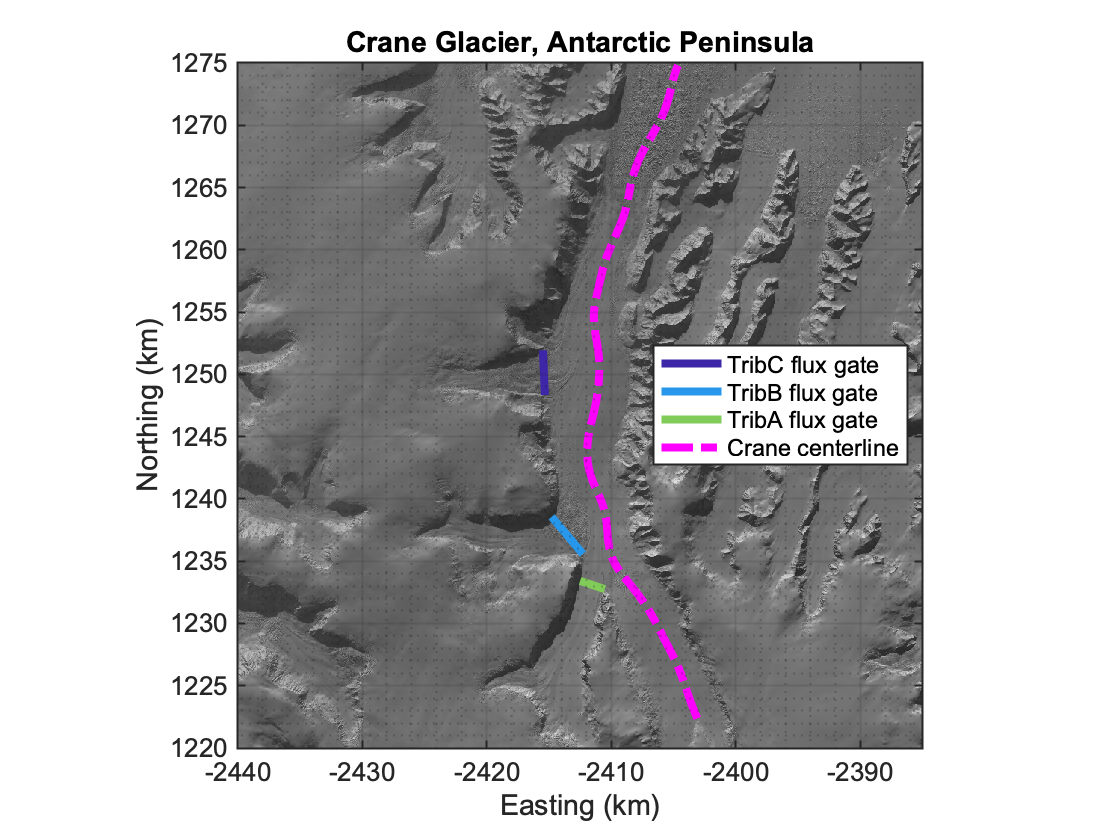

dispImage = 1; % =1 to display image

if dispImage
    %Display Landsat image
    cd([homepath,'data/Imagery/']);
    landsat = dir('LC08*20201015*B8.TIF');
    [im.LS,R] = readgeoraster(landsat.name);
    [ny,nx] = size(im.LS);
    im.LS = im.LS.*1.2;
    
    % Polar stereographic coordinates of image boundaries (from image metadata)
    im.X = linspace(min(R.XWorldLimits),max(R.XWorldLimits),nx);
    im.Y = linspace(min(R.YWorldLimits),max(R.YWorldLimits),ny);
    
    % Plot image, centerline, and fluxgates
    figure; imagesc(im.X/10^3,im.Y/10^3,flipud(im.LS)); colormap("gray");
        set(gca, 'YDir','normal','FontSize',13,'FontName','Arial','linewidth',1);
        xlabel('Easting (km)'); ylabel('Northing (km)');
        grid on; grid minor; axis equal; hold on;
        % Zoom to Crane 
        xlim([-2.44e3 -2.385e3]); ylim([1.220e3 1.275e3]);
        % Plot tributary flux gates
        plot(tribA.x_fg/10^3,tribA.y_fg/10^3,'-','color',col(1,:),'LineWidth',4,'DisplayName','TribC flux gate');
        plot(tribB.x_fg/10^3,tribB.y_fg/10^3,'-','color',col(2,:),'LineWidth',4,'DisplayName','TribB flux gate'); 
        plot(tribC.x_fg/10^3,tribC.y_fg/10^3,'-','color',col(3,:),'LineWidth',4,'DisplayName','TribA flux gate');
        % Plot Crane centerline
        plot(cl.x/10^3,cl.y/10^3,'-.m','LineWidth',4,'DisplayName','Crane centerline');
        legend('Location','east'); title('Crane Glacier, Antarctic Peninsula');
        hold off;
end 

**2. Calculate the total ice volume flux from each tributary to the Crane centerline.**

*Order of operations:* (use for calculating volume flux error for each bin and each tributary total)

- Calculate area of each bin (assume trapezoidal A):   `A_bin = H*W`

- Calculate assuming a (1) rectangular and (2) parabolic bed geometry, use the mean of these two, and incorporate the std. between the two into the uncertainty in the area. 

- Calculate volume flux of each bin:                              `V_bin = A_bin * U_fg = H*W*U_fg`

- Calculate total volume flux for each tributary:             `V_tot = sum(V_bin)`

- Calculate the error for the volume flux of each bin and the total flux from each tributary:    

                trib.sigma_`Vbin = V_bin*sqrt((sigma_H/H)^2+(sigma_W/W)^2+(sigma_U/U)^2)` 

                    Note: the width error is only present for the first and last points where the width was manually picked on the Landsat image.

                `trib.sigma_Vtot = sum(sigma_V_bin)`

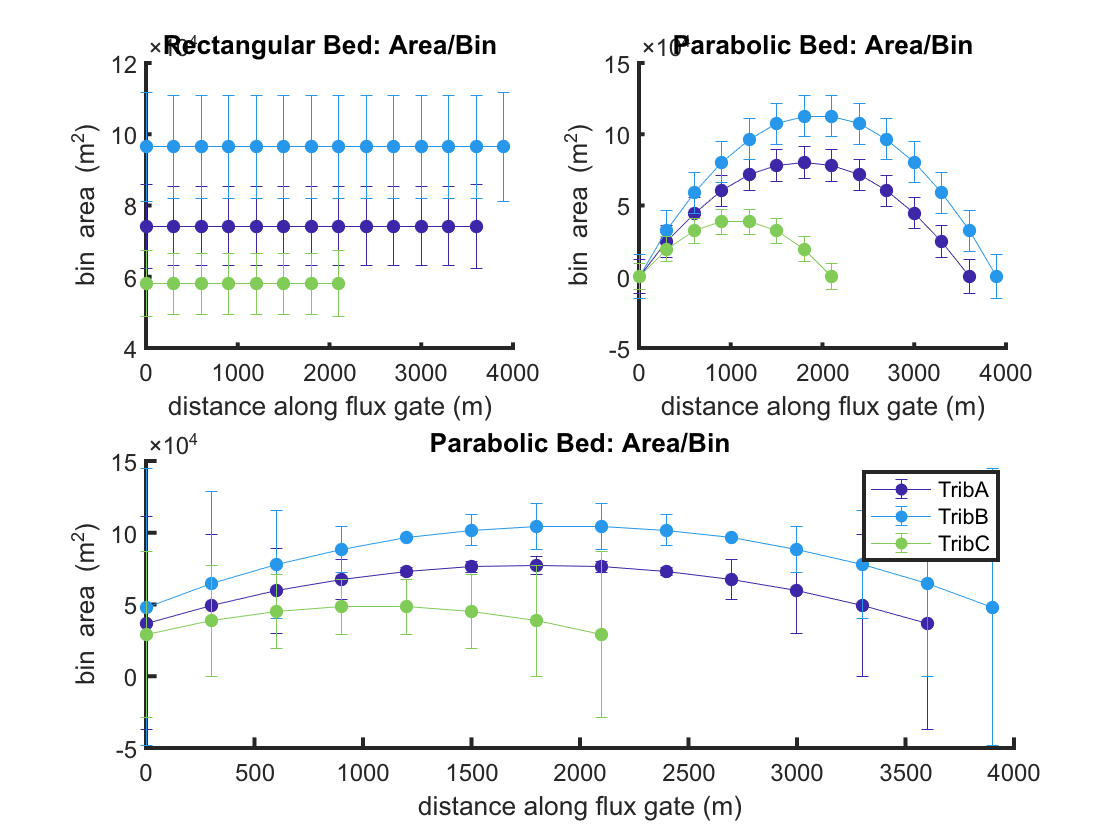

% Grab thickness and width at flux gate along centerline
    % Tributary A
    tribA.H = tribA.h_cl(1)-tribA.hb_cl(1); % TribA flux gate thickness at center point
        tribA.sigma_H = 40; % thickness uncertainty (m) (sigma_h + sigma_hb)
    tribA.W = sqrt((tribA.x_fg(end)-tribA.x_fg(1))^2+(tribA.y_fg(end)-tribA.y_fg(1))^2);% TribA flux gate width
    tribA.sigma_W=[15 zeros(1,length(tribA.x_fg)-2) 15]; % width uncertainty along fg (m)
    % Tributary B
    tribB.W = sqrt((tribB.x_fg(end)-tribB.x_fg(1))^2+(tribB.y_fg(end)-tribB.y_fg(1))^2);% (m) TribB flux gate width
    tribB.sigma_W=[15 zeros(1,length(tribB.x_fg)-2) 15]; % width uncertainty along fg (m)
    % Tributary C
    tribC.W = sqrt((tribC.x_fg(end)-tribC.x_fg(1))^2+(tribC.y_fg(end)-tribC.y_fg(1))^2);% (m) TribC flux gate width        
    tribC.sigma_W=[15 zeros(1,length(tribC.x_fg)-2) 15]; % width uncertainty along fg (m)

% Calculate cross-sectional area
 % 1. Rectangular bed geometry
    tribA.Arect_tot = tribA.H*tribA.W; % TribA total area (m)
        tribA.Arect_bins = tribA.Arect_tot/length(tribA.x_fg).*ones(1,length(tribA.x)); % TribA area in each bin (m^2) divided evenly between each point
    % Tributaries B & C - use ratio of widths to calculate area
    tribB.Arect_tot = (tribA.Arect_tot)*(tribB.W/tribA.W)./(nanmean(tribB.U_fg)/nanmean(tribA.U_fg)); % TribB total area (m)
        tribB.Arect_bins = tribB.Arect_tot/length(tribB.x_fg).*ones(1,length(tribB.x)); % TribB area in each bin (m^2) divided evenly between each point    
    tribC.Arect_tot = (tribA.Arect_tot)*(tribC.W/tribA.W)./(nanmean(tribC.U_fg)/nanmean(tribA.U_fg));
        tribC.Arect_bins = tribC.Arect_tot/length(tribC.x_fg).*ones(1,length(tribC.x)); % TribC area in each bin (m^2) divided evenly between each point
    
    % Calculate uncertainty in total areas (m^2)
    tribA.sigma_A_tot = abs(tribA.Arect_tot)*sqrt((sum(tribA.sigma_W)/tribA.W)^2+(tribA.sigma_H/tribA.H)^2);
    tribA.sigma_A_tot = abs(tribB.Arect_tot)*sqrt((sum(tribA.sigma_W)/tribB.W)^2+(tribA.sigma_H/tribA.H)^2);
    tribA.sigma_A_tot = abs(tribB.Arect_tot)*sqrt((sum(tribA.sigma_W)/tribB.W)^2+(tribA.sigma_H/tribA.H)^2);

    % Calculate uncertainty in bin areas (m^2)
    % initialize bin area uncertainties
    tribA.sigma_A_bins=zeros(1,length(tribA.x_fg)); 
    tribB.sigma_A_bins=zeros(1,length(tribB.x_fg));
    tribC.sigma_A_bins=zeros(1,length(tribC.x_fg));
    for i=1:length(tribA.x)
        tribA.sigma_A_bins(i)=abs(tribA.Arect_bins(i))*sqrt((tribA.sigma_W(i)/(tribA.W/length(tribA.x)))^2 ...
            +(tribA.sigma_H/tribA.H)^2);        
    end
    for i=1:length(tribB.x)
        tribB.sigma_A_bins(i)=abs(tribB.Arect_bins(i))*sqrt((tribB.sigma_W(i)/(tribB.W/length(tribB.x)))^2 ...
            +(tribA.sigma_H/tribA.H)^2);          
    end
    for i=1:length(tribC.x)
        tribC.sigma_A_bins(i)=abs(tribC.Arect_bins(i))*sqrt((tribC.sigma_W(i)/(tribC.W/length(tribC.x)))^2 ...
            +(tribA.sigma_H/tribA.H)^2);          
    end
    
% 2. Parabolic bed geometry
    % TribA
    tribA.Hpara_bins =  polyval(polyfit([tribA.x(1) tribA.x(round(length(tribA.x)/2)) tribA.x(end)],...
        [0 tribA.H 0],2),tribA.x); % TribA thickness (m)
    tribA.Apara_bins = tribA.Hpara_bins.*dx; % TribA bin areas (m^2)
    tribA.Apara_tot = sum(tribA.Apara_bins); % TribA total area (m^2)
    % Tributaries B & C - use ratio of widths to thickness at center point
    % TribB
    tribB.H = tribA.H*(tribB.W/nanmean(tribB.U_fg))/(tribA.W/nanmean(tribA.U_fg));
    tribB.Hpara_bins = polyval(polyfit([tribB.x(1) tribB.x(round(length(tribB.x)/2)) tribB.x(end)],...
        [0 tribB.H 0],2),tribB.x); % TribB thickness (m)
    tribB.Apara_bins =  tribB.Hpara_bins.*dx; % TribB area in each bin (m^2) 
    tribB.Apara_tot = sum(tribB.Apara_bins); % TribA total area (m^2)
    %TribC
    tribC.H = tribA.H*(tribC.W/nanmean(tribC.U_fg))/(tribA.W/nanmean(tribA.U_fg));
    tribC.Hpara_bins = polyval(polyfit([tribC.x(1) tribC.x(round(length(tribC.x)/2)) tribC.x(end)],...
        [0 tribC.H 0],2),tribC.x); % TribB thickness (m)
    tribC.Apara_bins =  tribC.Hpara_bins.*dx; % TribB area in each bin (m)  
    tribC.Apara_tot = sum(tribC.Apara_bins); % TribA total area (m^2)
 
% Calculate mean areas at each point from the two methods
for i=1:length(tribA.x)
    tribA.A_bins_mu(i) = nanmean([tribA.Apara_bins(i) tribA.Arect_bins(i)]);
    tribA.sigma_A_bins_mu(i) = abs(tribA.Apara_bins(i)-tribA.Arect_bins(i));
end
for i=1:length(tribB.x)
    tribB.A_bins_mu(i) = nanmean([tribB.Apara_bins(i) tribB.Arect_bins(i)]); 
    tribB.sigma_A_bins_mu(i) = abs(tribB.Apara_bins(i)-tribB.Arect_bins(i));
end
for i=1:length(tribC.x)
    tribC.A_bins_mu(i) = nanmean([tribC.Apara_bins(i) tribC.Arect_bins(i)]);  
    tribC.sigma_A_bins_mu(i) = abs(tribC.Apara_bins(i)-tribC.Arect_bins(i));
end

% Plot resulting areas
figure; 
    subplot(2,2,1); hold on; % rectangular areas
    errorbar(tribA.x,tribA.Arect_bins,tribA.sigma_A_bins,'.-','color',col(1,:),'markersize',20,'displayname','TribA');
    errorbar(tribB.x,tribB.Arect_bins,tribB.sigma_A_bins,'.-','color',col(2,:),'markersize',20,'displayname','TribB');
    errorbar(tribC.x,tribC.Arect_bins,tribC.sigma_A_bins,'.-','color',col(3,:),'markersize',20,'displayname','TribC');
    xlabel('distance along flux gate (m)'); ylabel('bin area (m^2)');
    set(gca,'fontsize',12,'linewidth',2); 
    title('Rectangular Bed: Area/Bin'); set(gca,'fontsize',12,'fontname','arial');  
    
    subplot(2,2,2); hold on; % parabolic areas
    errorbar(tribA.x,tribA.Apara_bins,tribA.sigma_A_bins,'.-','color',col(1,:),'markersize',20,'displayname','TribA');
    errorbar(tribB.x,tribB.Apara_bins,tribB.sigma_A_bins,'.-','color',col(2,:),'markersize',20,'displayname','TribB');
    errorbar(tribC.x,tribC.Apara_bins,tribC.sigma_A_bins,'.-','color',col(3,:),'markersize',20,'displayname','TribC');
    xlabel('distance along flux gate (m)'); ylabel('bin area (m^2)');
    set(gca,'fontsize',12,'linewidth',2); 
    title('Parabolic Bed: Area/Bin'); set(gca,'fontsize',12,'fontname','arial');     
    
    subplot(2,2,3:4); hold on; % mean areas and std
    errorbar(tribA.x,tribA.A_bins_mu,tribA.sigma_A_bins_mu,'.-','color',col(1,:),'markersize',20,'displayname','TribA');
    errorbar(tribB.x,tribB.A_bins_mu,tribB.sigma_A_bins_mu,'.-','color',col(2,:),'markersize',20,'displayname','TribB');
    errorbar(tribC.x,tribC.A_bins_mu,tribC.sigma_A_bins_mu,'.-','color',col(3,:),'markersize',20,'displayname','TribC');
    xlabel('distance along flux gate (m)'); ylabel('bin area (m^2)');
    set(gca,'fontsize',14,'linewidth',2); legend;
    title('Parabolic Bed: Area/Bin'); set(gca,'fontsize',12,'fontname','arial');   

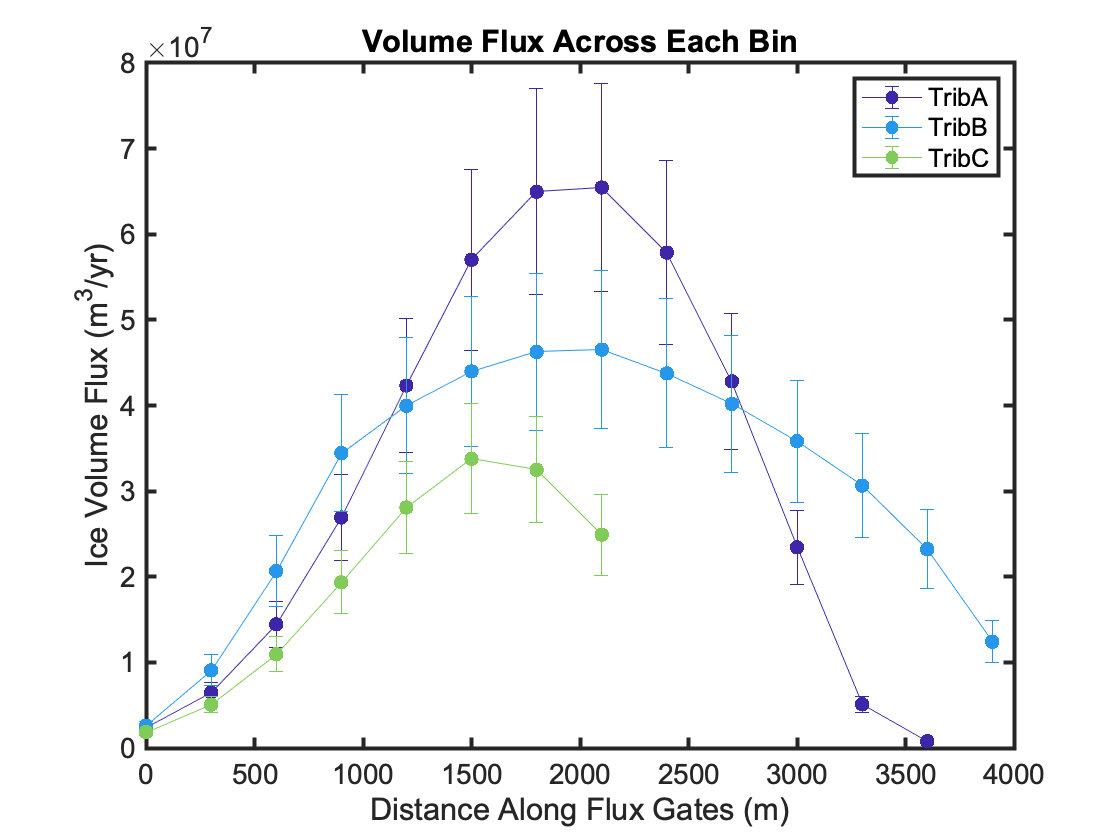

    % Calculate velocity along flux gates (no TribC velocity data - use
    % TribA velocity)
    tribC.U_fg = interp1(tribA.x,tribA.U_fg,tribC.x); % m/yr
    
    % Calculate total ice volume flux across flux gate
    tribA.V = tribA.U_fg.*tribA.A_bins_mu; tribA.V_tot = sum(tribA.V); % m^3/yr
    tribB.V = tribB.U_fg.*tribB.A_bins_mu; tribB.V_tot = sum(tribB.V); % m^3/yr
    tribC.V = tribC.U_fg.*tribC.A_bins_mu; tribC.V_tot = sum(tribC.V); % m^3/yr     

    % Calculate volume error
    tribA.V_err = abs(tribA.V).*sqrt((tribA.U_err_fg/tribA.U_fg).^2+(tribA.sigma_A_bins/tribA.A_bins_mu).^2); % m^3/yr
    tribB.V_err = abs(tribB.V).*sqrt((tribB.U_err_fg/tribB.U_fg).^2+(tribA.sigma_A_bins/tribA.A_bins_mu).^2); % m^3/yr
    tribC.V_err = abs(tribC.V).*sqrt((tribC.U_err_fg/tribC.U_fg).^2+(tribA.sigma_A_bins/tribA.A_bins_mu).^2); % m^3/yr
    tribA.V_tot_err = sum(tribA.V_err); % m^3/yr
    tribB.V_tot_err = sum(tribB.V_err); % m^3/yr
    tribC.V_tot_err = sum(tribC.V_err); % m^3/yr
    
% Plot results
figure; % volume flux at across each bin
        errorbar(tribA.x,tribA.V,tribA.V_err,'.-','color',col(1,:),'markersize',20,'displayname','TribA');
        hold on; errorbar(tribB.x,tribB.V,tribB.V_err,'.-','color',col(2,:),'markersize',20,'displayname','TribB');
        errorbar(tribC.x,tribC.V,tribC.V_err,'.-','color',col(3,:),'markersize',20,'displayname','TribC');
        xlabel('Distance Along Flux Gates (m)'); ylabel('Ice Volume Flux (m^3/yr)');
        set(gca,'fontsize',14,'fontname','arial','linewidth',2); 
        legend('Location','northeast');
        title('Volume Flux Across Each Bin');

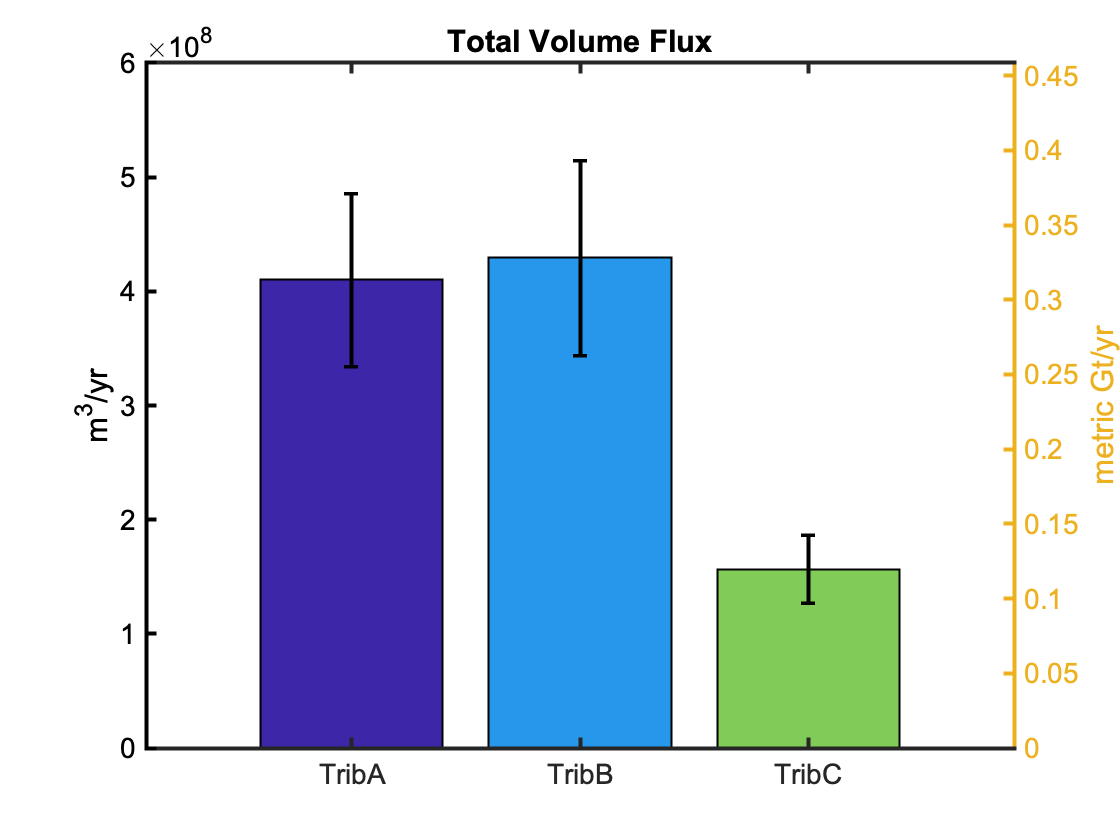

figure; % total volume flux from each tributary
        Tribs = categorical({'TribA','TribB','TribC'}); Tribs = reordercats(Tribs,{'TribA','TribB','TribC'});
        tribs_err = [tribA.V_tot_err tribB.V_tot_err tribC.V_tot_err];
        b = bar(Tribs,[tribA.V_tot tribB.V_tot tribC.V_tot]); hold on;
        er = errorbar(Tribs,[tribA.V_tot tribB.V_tot tribC.V_tot],tribs_err,tribs_err);
        er.Color = [0 0 0]; er.LineStyle = 'none'; er.LineWidth = 2;
        b.FaceColor='flat'; b.CData(:,:) = col(1:3,:); b.LineWidth=1;
        title('Total Volume Flux'); set(gca,'fontsize',14,'fontname','arial');
        ylabel('m^3/yr'); set(gca,'fontsize',14,'linewidth',2);
        yyaxis right
            ylim([0 5e8*917/10^12]); % metric Gt/yr
            ylabel('metric Gt/yr');

#### 3. Integrate over the width and distance between centerline points to calculate thickness input at each point. 

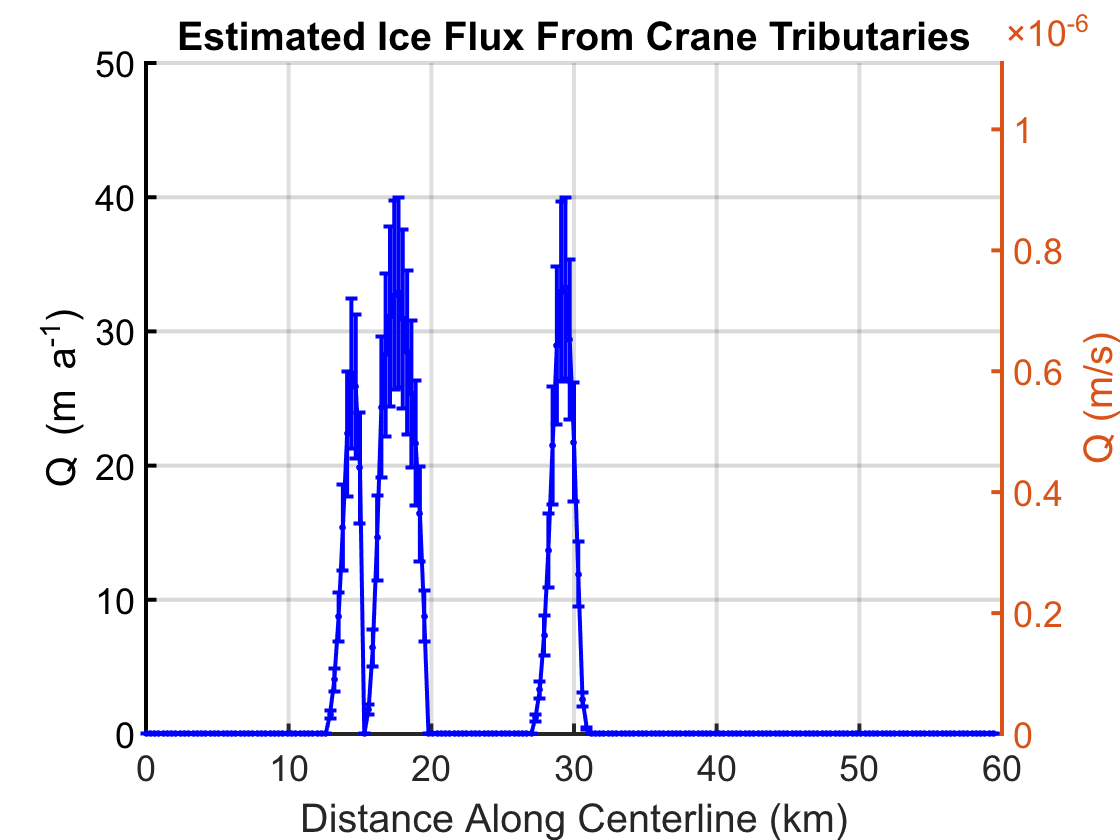

% Estimate indices where tributary flux gates meets the centerline 
    tribA.cl_bnds = dsearchn([transpose(cl.x) transpose(cl.y)],...
        [tribA.x_fg(1) tribA.y_fg(1)]);
        tribA.cl_bnds = [tribA.cl_bnds(1) tribA.cl_bnds(1)+length(tribA.x)-1];    
    tribB.cl_bnds = dsearchn([transpose(cl.x) transpose(cl.y)],...
        [tribB.x_fg(1) tribB.y_fg(1)]);
        tribB.cl_bnds = [tribB.cl_bnds(1) tribB.cl_bnds(1)+length(tribB.x)-1];
    tribC.cl_bnds = dsearchn([transpose(cl.x) transpose(cl.y)],...
        [tribC.x_fg(1) tribC.y_fg(1)]);
        tribC.cl_bnds = [tribC.cl_bnds(1) tribC.cl_bnds(1)+length(tribC.x)-1];
    
% Divide the volume over the average width of Crane at these determined windows
% and the distance between each point 
    tribA.Q = tribA.V./transpose(nanmean(cl.W(tribA.cl_bnds(1):tribA.cl_bnds(2)))); % m^2/yr
    tribB.Q = tribB.V./transpose(nanmean(cl.W(tribB.cl_bnds(1):tribB.cl_bnds(2)))); % m^2/yr 
    tribC.Q = tribC.V./transpose(nanmean(cl.W(tribC.cl_bnds(1):tribC.cl_bnds(2)))); % m^2/yr 
    
    % calculate thickness added at each point by dividing by the distance
    % between points, calculate error
    tribA.Q = tribA.Q./dx; tribA.Q_err = tribA.Q*sqrt((tribA.V_err/tribA.V)^2+(tribA.h_err(1)/dx)^2);% m/yr
    tribB.Q = tribB.Q./dx; tribB.Q_err = tribB.Q*sqrt((tribB.V_err/tribB.V)^2+(tribB.h_err(1)/dx)^2);% m/yr
    tribC.Q = tribC.Q./dx; tribC.Q_err = tribC.Q*sqrt((tribC.V_err/tribC.V)^2+(tribC.h_err(1)/dx)^2);% m/yr

    % Calculate total tributary flux for each point along centerline
    Q = zeros(1,length(cl.x)); Q_err = zeros(1,length(cl.x));
    for i=1:length(x)
        if i>=tribC.cl_bnds(1) && i<=tribC.cl_bnds(2)
            Q(i)=tribC.Q(i-tribC.cl_bnds(1)+1); % m/yr
            Q_err(i) = tribC.Q_err(i-tribC.cl_bnds(1)+1); % m/yr
        elseif i>=tribB.cl_bnds(1) && i<=tribB.cl_bnds(2)
            Q(i)=tribB.Q(i-tribB.cl_bnds(1)+1); % m/yr
            Q_err(i) = tribB.Q_err(i-tribB.cl_bnds(1)+1); % m/yr
        elseif i>=tribA.cl_bnds(1) && i<=tribA.cl_bnds(2)
            Q(i)=tribA.Q(i-tribA.cl_bnds(1)+1); % m/yr
            Q_err(i)=tribA.Q_err(i-tribA.cl_bnds(1)+1); % m/yr
        end
    end  
    
% Plot resulting Q
figure; 
    hold on; errorbar(x/10^3,Q,Q_err,'.-b','markersize',10,'linewidth',2);
    grid on; xlabel('Distance Along Centerline (km)');
    ylabel('Q (m a^{-1})'); set(gca,'fontname','arial','fontsize',18,'linewidth',2);
    title('Estimated Ice Flux From Crane Tributaries');  
    %ylim([0 100]);
    yyaxis right
        ylim([0 35./3.1536e7]); ylabel('Q (m/s)');

#### Save the results! 

cd([homepath,'inputs-outputs/']);
tribFlux.Q = Q; % m/yr
tribFlux.Q_err = Q_err; % m/yr
tribFlux.x = x; % m
tribFlux.cl = cl; % centerline coordinates

tribs.tribA = tribA; tribs.tribB = tribB; tribs.tribC = tribC;

save('tributaryFluxes.mat','tribFlux');
disp('tributary fluxes saved');

tributary fluxes saved
